# Script di testing della classe filtro del primo ordine che poi viene utilizzata nei controllori

clc
close all
clear all
s  = tf('s');
%definizione dei parametri del filtro
Tf = 1/100;
st = 0.001;
%generazione dei filtri in varri  modi per verifica
Fs = 1/(1+s*Tf);
Fs_d = c2d(Fs,st,'tustin')

Fs_d =
 
  0.04762 z + 0.04762
  -------------------
      z - 0.9048
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties



Fpb = tf(1,[Tf 1]);
%discretizzazione filtro in z
Fpb_d = c2d(Fpb,st,'tustin')

Fpb_d =
 
  0.04762 z + 0.04762
  -------------------
      z - 0.9048
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties



Fpb_d_num = Fpb_d.Numerator{1};
Fpb_d_den = Fpb_d.Denominator{1};
%plot dei dati per conftronto dei parametri calclolati dalla classe
nu_fpb = Fpb_d_num(1)

nu_fpb = 0.0476

num1_fpb = Fpb_d_num(2)

num1_fpb = 0.0476

ny_fpb = Fpb_d_den(1)

ny_fpb = 1

nym1_fpb = Fpb_d_den(2)

nym1_fpb = -0.9048


numC0d=Fs_d.Numerator{1}

numC0d =     0.0476    0.0476


denC0d=Fs_d.Denominator{1}

denC0d =     1.0000   -0.9048



filtro = FilterFirstOrder(st,Tf);
filtro.nu_fpb

ans = 0.0476

filtro.num1_fpb

ans = 0.0476

filtro.ny_fpb

ans = 1

filtro.nym1_fpb

ans = -0.9048

filtro.starting(0);

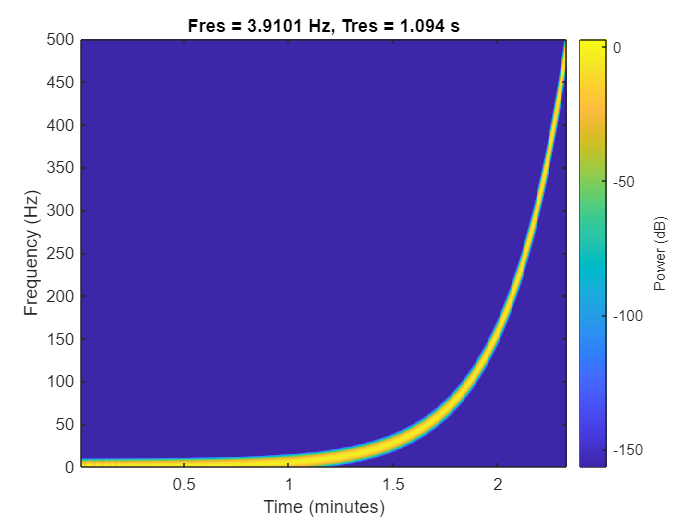

%generazione di un seganel chirp per scorrere tutte le frequenze e vedere
%l'attenuazione del segnale in uscita
t=(0:st:140)';
w0=1; %rad/s
w1=pi/st; %rad/s     Fs=1/Ts, Ws=2*pi/Ts, 0.5*Ws=pi/Ts -> valore alto tipo val max dato
input = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');
pspectrum(input,1/st,'spectrogram');

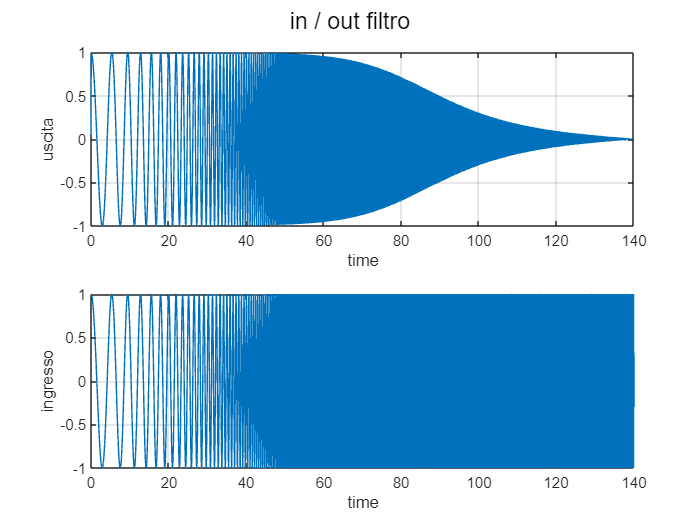


output=zeros(length(t),1);
for idx=1:length(t)
    output(idx,:)=filtro.computeAction(input(idx));
end
%plot nel tempo dei risultati
figure(1)
subplot(2,1,1)
plot(t,output(:))
xlabel('time')
ylabel('uscita')
grid on

subplot(2,1,2)
plot(t,input)
xlabel('time')
ylabel('ingresso')
grid on

sgtitle('in / out filtro')

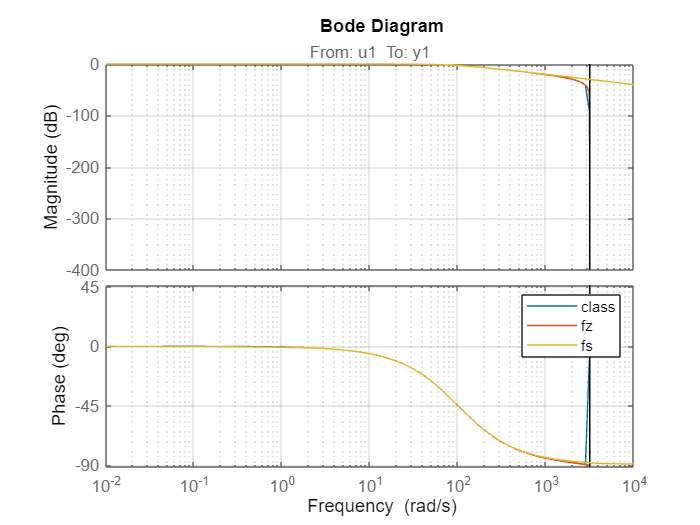


ident = iddata(output,input,st);
f_ident = spafdr(ident);
figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
bode(f_ident,bode_opts)
hold on 
bode(Fpb_d)
bode(Fs)
grid on
legend('class','fz','fs')
hold off